
% // Ali Yasar 26021 //
% This code iterates a degree of freedom to approxiamte a exact solution with using a weighted residual method
% For that code shape functions considered as Ni = sin(i*pi*x/2/L) and Ni=1-cos(i*pi*x/4/L)
clear all ; 
clc;

syms x k

A = pi*10^-4; %m^2
L = 1; %m
E = 120*10^9; %Pa
p = 2700; %kg/m^3
Fmax = 50;%N/m
g = 9.81; %m/s^2
f = g*p;
e = 1*10^-3;
error = 1;

%Exact solution
% u_exact(x)=((Fmax*(x^3))/E/A/L/6)+((((-f)/E/2) - (Fmax/E/A/2))*(x^2))+((f*L/E)+(Fmax*L/2/E/A))*x;
% simplify(U);
DOF = 2;
while error > e 
K_A = zeros(DOF);
F = zeros(DOF,1);
  %For building a stiffness matrix
      for i = 1:DOF          
             if mod(i,2)==1
                 N_A(i)=sin(i*pi*x/2/L);
                 N_dx_A(i)=(i*pi/2/L)*cos(i*pi*x/2/L);
                 else
                 N_A(i)=1-cos(i*pi*x/4/L);
                 N_dx_A(i)=(i*pi/4/L)*sin(i*pi*x/4/L);
             end      
      end
  for a = 1:DOF
        for b = 1:DOF
        %To build stiffness matrix  
            TF = N_dx_A(a)*E*A*N_dx_A(b);
            K_A(a,b) = int(TF,[0,L]);
%         For building  a force matrix
            T1 =  N_A(a)*f*A;
            T2 =  Fmax*(N_A(a))*(1-(x/L));
            T1i = int(T1,[0,L]);
            T2i = int(T2,[0,L]);
            F(a,1) = T1i+T2i;
        end
  end
    
% I multiply both side with a inverse of a stiffness matrix    
D = K_A\F;

%I build a Uh function from there 
   Uh(x)=N_A*D; 
   U(x)=((Fmax*(x^3))/E/A/L/6)+((((-f)/E/2) - (Fmax/E/A/2))*(x^2))+((f*L/E)+(Fmax*L/2/E/A))*x;
   
Uh2 = Uh^2;
UhU = 2*Uh*U;
U2 = U^2;
errorNum = double(sqrt(int((Uh-U)^2,[0,L])));
errorDenum = double(sqrt(int(U^2,[0,L])));
DOF
error = double(errorNum/errorDenum)
errorarray(DOF-1) = error;
DOFarray(DOF-1)=DOF;
%This if statement breaks a loop when error less than a cirtaiın error treshold. 
DOF  = DOF + 1;
end

DOF =      2


error =    0.044388735449588


DOF =      3


error =    0.016466672774102


DOF =      4


error =    0.001129608373175


DOF =      5


error =      1.416518358512762e-04


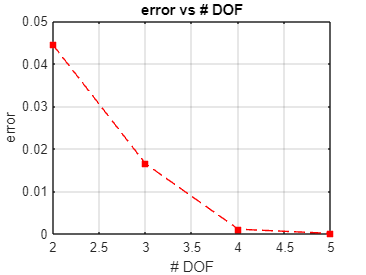

plot(DOFarray,errorarray,'--rs','MarkerFaceColor','r');
title('error vs # DOF');
xlabel('# DOF');
ylabel('error');
grid on